# Sessió 10

## 1. App Classification Learner

L’objectiu d’aquesta pràctica és aprendre a classificar mostresa partir dels seus vectors de caracterìstiques. Usarem la App Classification learner de Matlab. Trobareu la informació necessària a:

https://uk.mathworks.com/help/stats/train-decision-trees-in-classification-learner-app.html

https://uk.mathworks.com/help/stats/train-classification-models-in-classification-learner-app.html

Podeu utilitzar el dataset Fisher iris (tot un clàssic) i experimentar amb diferents classificadors. En acabar heu de ser capaços de:

- Tunnejar correctament els paràmetres d’un classificador

- Probar diferents classificadors i escollir-ne els que donin millors resultats

- Fer experiments amb rigor (p.ex: cross-validation)

- Presentar els resultats de forma correcta ( corba RoC, matriu de confusió...)

%fishertable = readtable('fisheriris.csv');

%view(trainedModel.ClassificationTree,'Mode','graph');
%yfit = trainedModel.predictFcn(fishertable)

## 2. Classificació automàtica d’espècies arbòries

Un cop domineu la app Clasification learner, es planteja un problema de classificació amb imatges reals. Dins la tasca corresponent a la sessió 10 a Atenea, trobareu imatges de fulles de roure, faig i plàtan. Entreneu varios classificadors per aquestes tres espècies usant com a vectors de característiques els seus descriptors de Fourier. Es demana un informe (en pdf) que inclogui el codi usat per a obtenir els descriptors, la descripció dels experiments realitzats, els classificadors que han funcionat millor i els resultats obtinguts. Indiqueu quines caracaterístiques del vector són necessàries per a la correcta classificació, i quines no són significatives.

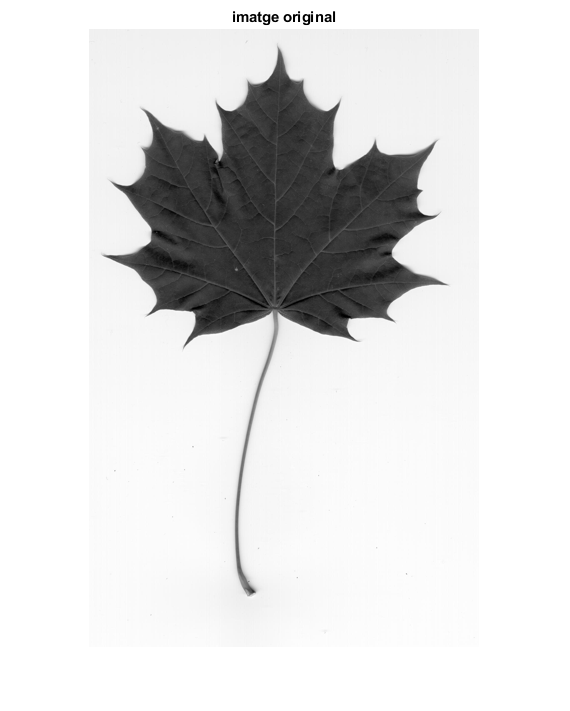

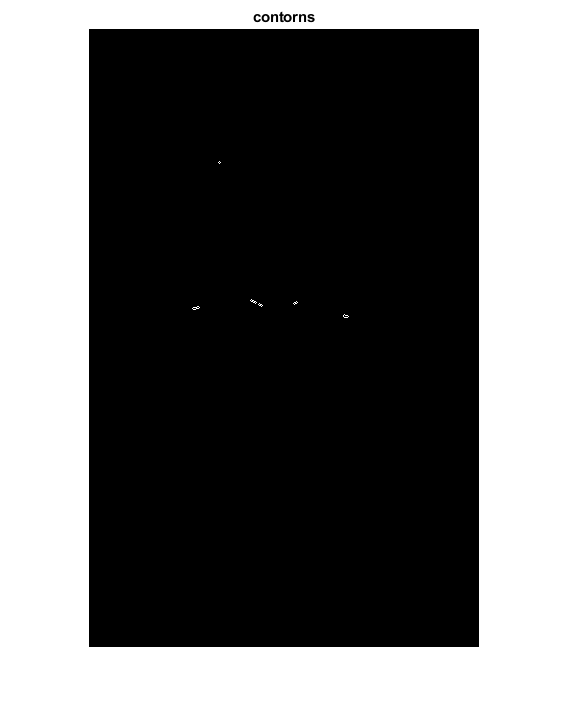

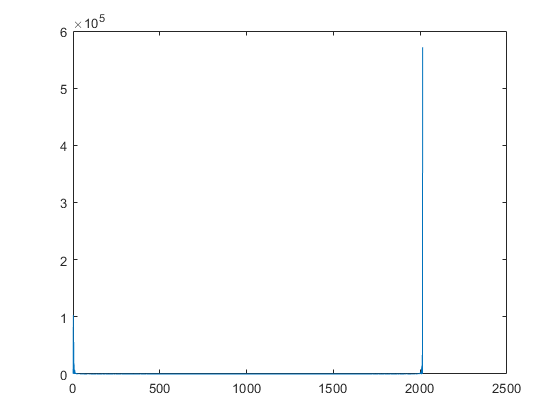

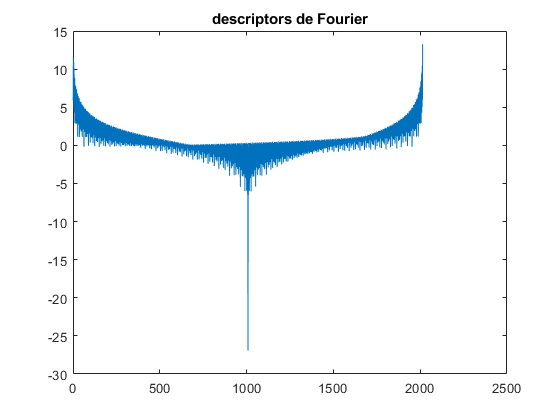

ans = 0

im=imread('Erable/l2nr001.jpg');
im = rgb2gray(im);
fourier(im)

Funciones

function f = fourier(im)
    % no cal tan gran
    im=imresize(im,1/4);
    imshow(im), title('imatge original')
    % obtenim el contorn
    ero=imerode(im,strel('disk',1));
    cont=xor(ero,im);
    figure,imshow(cont), title('contorns')
    % obtenim les coordenades del contorn
    [fila col] = find(im,1); % Busquem el primer píxel
    B = bwtraceboundary(im,[fila col],'E'); %direccio est a l'atzar
    mig=mean(B);
    B(:,1)=B(:,1)-mig(1);
    B(:,2)=B(:,2)-mig(2);
    % Convertim les coordenades a complexes
    s= B(:,1) + i*B(:,2);
    % Cal que la dimensio del vector sigui parell
    [mida bobo]=size(B);
    if(mida/2~=round(mida/2))
    s(end+1,:)=s(end,:); %dupliquem l'ultim
    mida=mida+1;
    end
    % Calculem la Fast Fourier Transform
    z=fft(s);
    % representem l’espectre
    figure,plot(abs(z))
    % ho displaiem logaritmic perque no es veu res
    figure,plot(log(abs(z))), title ('descriptors de Fourier')
    f= 0;
end